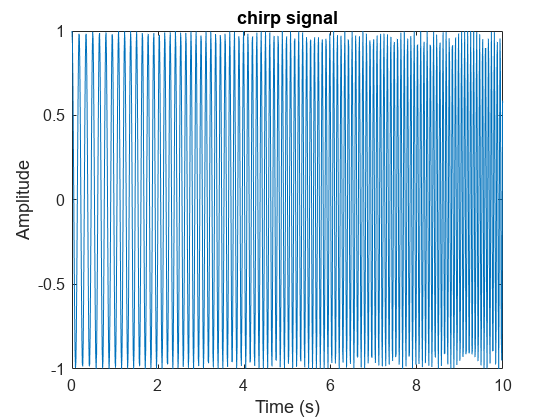

%Q1
a=1+mod(256,3);
Fs=100;
t=0:1/Fs:10-1/Fs;
f1=2+2*a;
f2=5+5*a;
t2=10;
y=chirp(t,f1,t2,f2);
%Q1-a
plot(t,y)
title('chirp signal');
xlabel('Time (s)')
ylabel('Amplitude');

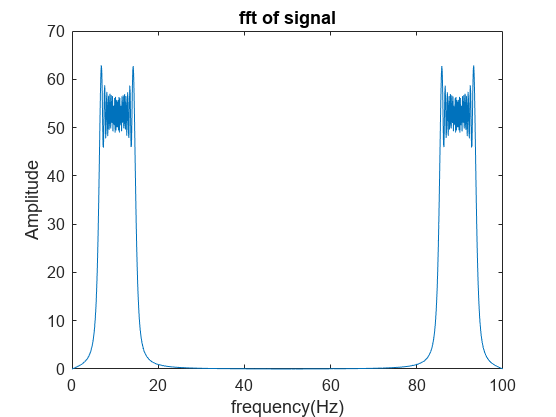

%Q1-b
N=length(y);
Y=fft(y);
freq_axis=Fs*((0:N-1)/N);
mag=abs(Y);
figure;
plot(freq_axis,mag)
xlabel('frequency(Hz)')
ylabel('Amplitude');
title('fft of signal')

% [~, idx] = max(mag(2:end));
% pitch_fundamental= freq_axis(idx);
[pks, peak_indices] = findpeaks(abs(Y))

pks =    62.8878   58.7725   57.3954   56.5873   56.9964   56.7104   56.5063   54.5446   56.1134   56.3532   55.7055   55.3725   55.7000   56.3401   56.0952   54.5291   56.4706   56.6640   56.9388   56.5295   57.3202   58.6746   62.7546   62.7546   58.6746   57.3202   56.5295   56.9388   56.6640   56.4706   54.5291   56.0952   56.3401   55.7000   55.3725   55.7055   56.3532   56.1134   54.5446   56.5063   56.7104   56.9964   56.5873   57.3954   58.7725   62.8878


peak_indices =     69    77    82    86    89    92    95    97   100   102   104   106   108   110   112   115   117   120   123   126   130   135   143   859   867   872   876   879   882   885   887   890   892   894   896   898   900   902   905   907   910   913   916   920   925   933


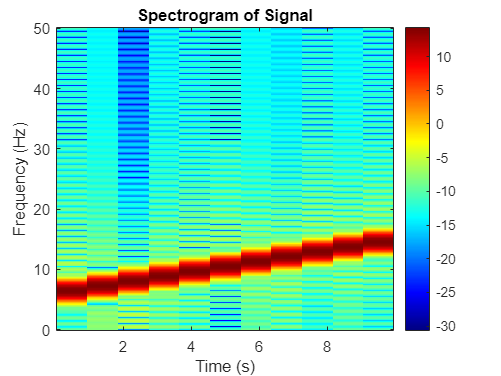



%Q1-c
length_seg=100;
window=hamming(length_seg);
overlap=10;

[mag,freq,t]= spectrogram(y,window,overlap,length(y),Fs);
figure;
imagesc(t, freq, 10*log10(abs(mag)));
axis xy;
colormap('jet');
xlabel('Time (s)')
ylabel('Frequency (Hz)');
title('Spectrogram of Signal');
colorbar;

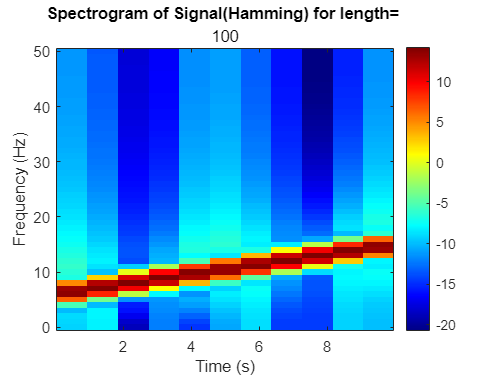

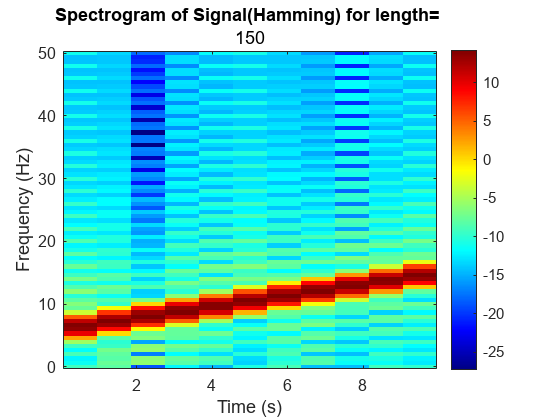

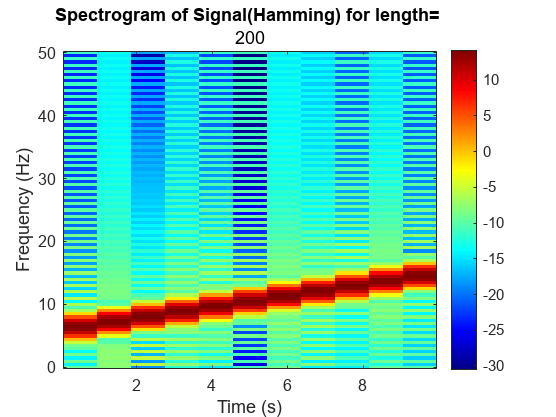

%Q1-comparing for different window lengths
% Hamming
a=1+mod(256,3);
Fs=100;
t=0:1/Fs:10-1/Fs;
f1=2+2*a;
f2=5+5*a;
t2=10;
y=chirp(t,f1,t2,f2);
samples_len=[100;150;200];

for i=1:3
    sample=y(1:samples_len(i));
    N=length(sample);
    window=hamming(length_seg);
    overlap=10;

   [mag,freq,t]= spectrogram(y,window,overlap,N,Fs);
   figure;
   imagesc(t, freq, 10*log10(abs(mag)));
   axis xy;
   colormap('jet');
   xlabel('Time (s)')
   ylabel('Frequency (Hz)');
   title('Spectrogram of Signal(Hamming) for length= ',num2str(samples_len(i)));
   colorbar;
    

   
end   

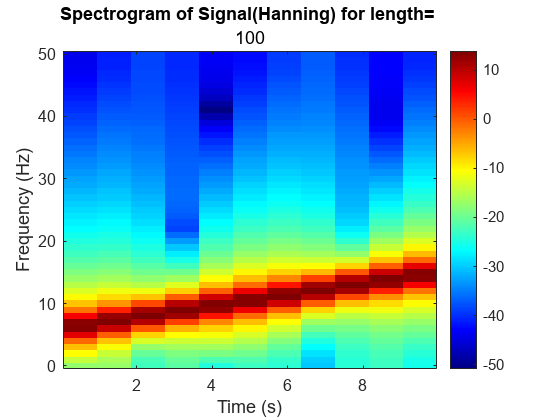

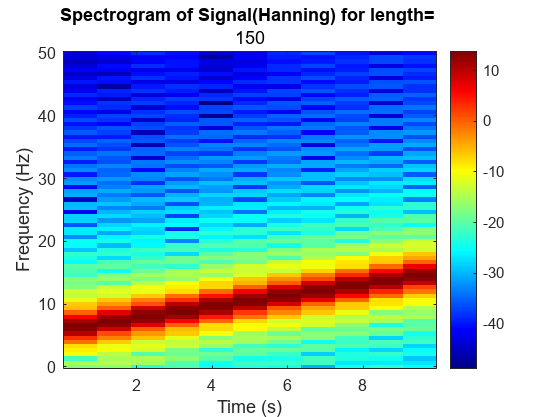

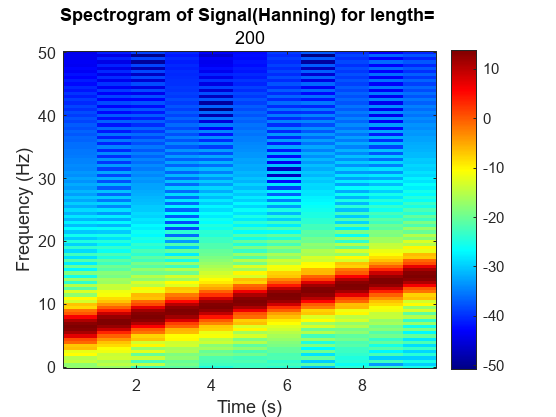

%Q1-comparing for different window lengths
% Hanning
a=1+mod(256,3);
Fs=100;
t=0:1/Fs:10-1/Fs;
f1=2+2*a;
f2=5+5*a;
t2=10;
y=chirp(t,f1,t2,f2);
samples_len=[100;150;200];

for i=1:3
    sample=y(1:samples_len(i));
    N=length(sample);
    window=hann(length_seg);
    overlap=10;

   [mag,freq,t]= spectrogram(y,window,overlap,N,Fs);
   figure;
   imagesc(t, freq, 10*log10(abs(mag)));
   axis xy;
   colormap('jet');
   xlabel('Time (s)')
   ylabel('Frequency (Hz)');
   title('Spectrogram of Signal(Hanning) for length= ',num2str(samples_len(i)));
   colorbar;
    

   
end   

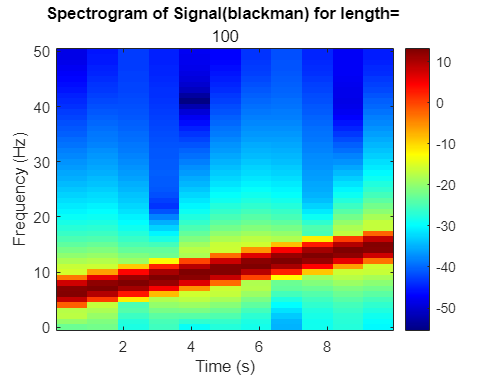

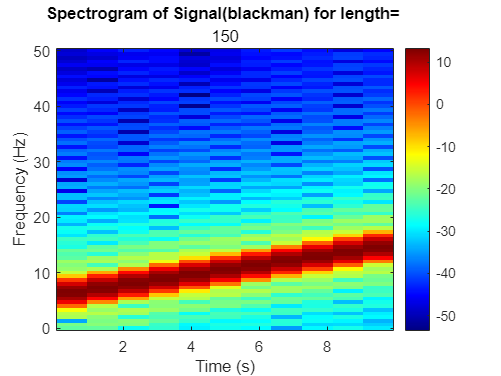

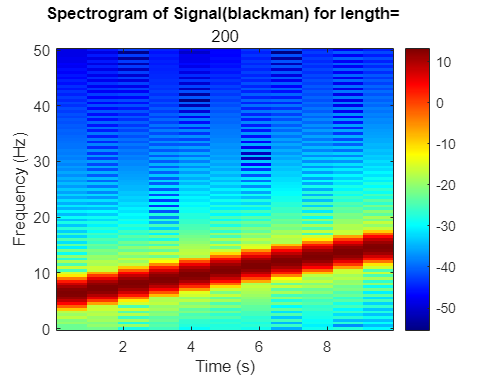

%Q1-comparing for different window lengths
% Blackman
a=1+mod(256,3);
Fs=100;
t=0:1/Fs:10-1/Fs;
f1=2+2*a;
f2=5+5*a;
t2=10;
y=chirp(t,f1,t2,f2);
samples_len=[100;150;200];

for i=1:3
    sample=y(1:samples_len(i));
    N=length(sample);
    window=blackman(length_seg);
    overlap=10;

   [mag,freq,t]= spectrogram(y,window,overlap,N,Fs);
   figure;
   imagesc(t, freq, 10*log10(abs(mag)));
   axis xy;
   colormap('jet');
   xlabel('Time (s)')
   ylabel('Frequency (Hz)');
   title('Spectrogram of Signal(blackman) for length= ',num2str(samples_len(i)));
   colorbar;
    

   
end   

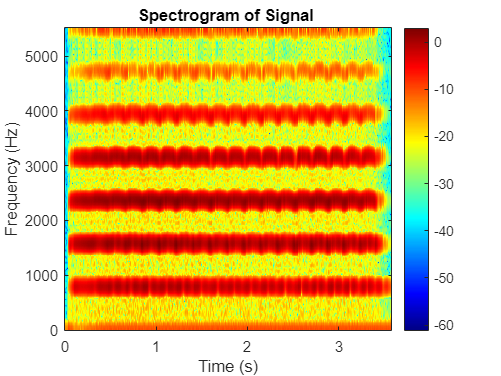

%Q2
[y,Fs]=audioread("instru2.wav");
length_seg=100;
window=hamming(length_seg);
overlap=0;

[mag,freq,t]=spectrogram(y,window,overlap,length(y),Fs);
figure;
imagesc(t, freq, 10*log10(abs(mag)));
axis xy;
colormap('jet');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal ');
colorbar;


f0=pitch(y,Fs);
pitch_spectro=max(f0)

pitch_spectro = 393.7500

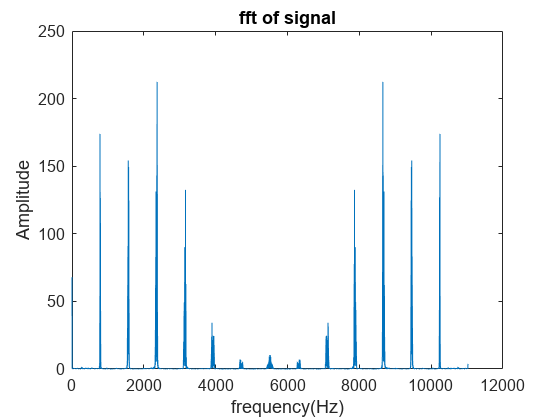


N=length(y);
Y=fft(y);
freq_axis=Fs*((0:N-1)/N);
mag=abs(Y);
figure;
plot(freq_axis,mag)
xlabel('frequency(Hz)')
ylabel('Amplitude');
title('fft of signal')



N=length(y);
Y=fft(y);
freq_axis=Fs*((0:N-1)/N);
mag=abs(Y);
[~, idx] = max(mag(2:end));
pitch_fundamental= freq_axis(idx)

pitch_fundamental = 2.3688e+03

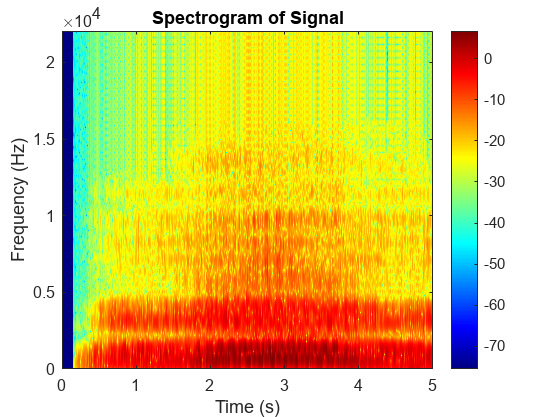

[y,Fs]=audioread('Opera.wav');
length_seg=100;
window=hamming(length_seg);
overlap=0;

[mag,freq,t]=spectrogram(y,window,overlap,length(y),Fs);
figure;
imagesc(t, freq, 10*log10(abs(mag)));
axis xy;
colormap('jet');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal');
colorbar;

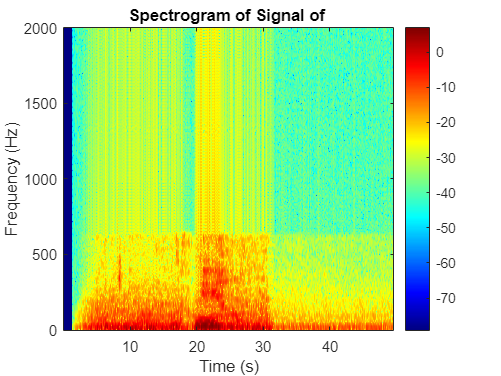

[audio_name,Fs]=audioread('my_name.wav');
Fs_new=4000;
y=resample(audio_name,Fs_new,Fs);
Fs=Fs_new;
length_seg=200;
window=hamming(length_seg);
overlap=10;

[mag,freq,t]=spectrogram(audio_name,window,overlap,length(audio_name),Fs);
figure;
imagesc(t, freq, 10*log10(abs(mag)));
axis xy;
colormap('jet');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Signal of ');
colorbar;